%CONTROL LQR DESCENTRALIZADO.
clc; clear all; close all;
A = [-3.32 3.32 0;
    3.32 -3.32-2.67 2.67;
    0 2.67 -2.67-1]

A =    -3.3200    3.3200         0
    3.3200   -5.9900    2.6700
         0    2.6700   -3.6700


B = [1 20 0; 20 1 0; 0 0 1]

B =      1    20     0
    20     1     0
     0     0     1


C = eye(3)

C =      1     0     0
     0     1     0
     0     0     1


D = zeros(3)

D =      0     0     0
     0     0     0
     0     0     0



Gss = ss(A,B,C,D);
Gs = tf(Gss)

Gs =
 
  From input 1 to output...
            s^2 + 76.06 s + 258.5
   1:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
           20 s^2 + 143.1 s + 255.9
   2:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
                53.4 s + 186.2
   3:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
  From input 2 to output...
           20 s^2 + 196.5 s + 309.3
   1:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
            s^2 + 73.39 s + 255.9
   2:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
                2.67 s + 186.2
   3:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
  From input 3 to output...
                    8.864
   1:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
                2.67 s + 8.864
   2:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.

eees = ss(Gs(2,1))

eees =
 
  A = 
           x1      x2      x3
   x1  -12.98  -4.488  -1.108
   x2       8       0       0
   x3       0       1       0
 
  B = 
       u1
   x1   8
   x2   0
   x3   0
 
  C = 
          x1     x2     x3
   y1    2.5  2.236  3.998
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



% G(a,b) <---- estas cordenadas e consigue en RGA
% C(b,a) ---> G(a,b)
% pares = Pares_Desc(Gs)
Q = diag([100;100;100])

Q =    100     0     0
     0   100     0
     0     0   100


R = 0.001

R = 1.0000e-03

Cs = tf(zeros(3));
Cs(1,2) = pidtune(Gs(2,1),'PID')

Cs =
 
  From input 1 to output...
   1:  0
 
   2:  0
 
   3:  0
 
  From input 2 to output...
       0.04126 s + 0.02854
   1:  -------------------
                s
 
   2:  0
 
   3:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
   3:  0
 
Continuous-time transfer function.
Model Properties


Glc_12 = LQR_desc(Gs(1,2),Q,R) 

Glc_12 =
 
  A = 
          x1     x2     x3
   x1  -2539  -2829  -2530
   x2      8      0      0
   x3      0      1      0
 
  B = 
          u1
   x1  523.5
   x2      0
   x3      0
 
  C = 
          x1     x2     x3
   y1    2.5  3.071  4.832
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


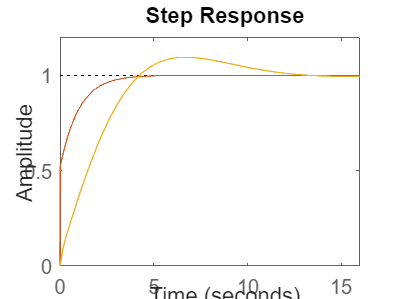

Cs(3,3) = pidtune(Gs(3,3),'PID'); 


Glc_21= feedback(Gs(2,1)*Cs(1,2),eye(1));
Glc_33 = feedback(Gs(2,1)*Cs(1,2),eye(1));

step(Glc_21), hold on;
step(Glc_12)
step(Glc_33)

function Pares = Pares_Desc(G)
Gdc = dcgain(G);
RGA=Gdc.*(Gdc')^-1 ;
[nRows, nCols] = size(RGA);
pairs = [];
for i = 1:nRows
    for j = 1:nCols
        pairs = [pairs; RGA(i, j), i, j]; 
    end
end

pairs_sorted = sortrows(pairs,'descend');
pairs= pairs_sorted(1:end,2:3) ;
selected_pairs = [];
rows_used = [];
cols_used = [];
for i = 1:size(pairs, 1)
    row = pairs(i, 1);
    col = pairs(i, 2);
    
    if ~ismember(row, rows_used) && ~ismember(col, cols_used)
        selected_pairs = [selected_pairs; row, col];
        rows_used = [rows_used, row];
        cols_used = [cols_used, col];
    end
    
    if size(selected_pairs, 1) == nRows
        break;
    end
end
Pares = selected_pairs;
end

function LqrD = LQR_desc(Gs,Q,R)

    Gss = ss(Gs);
    A = Gss.A;
    B = Gss.B;
    C = Gss.C;
    D = Gss.D;
    K = lqr(A,B,Q,R);
    Kr = inv(-(C-D*K)*(A-B*K)^-1*B+D);
    
    %Cerramos el Lazo
    ACL = A-B*K;
    BCL = B*Kr;
    CCL = C-D*K;
    DCL = D*Kr;
    
    GLC = ss(ACL,BCL,CCL,DCL);
    
    
    LqrD = GLC;


end